%calculating the mean first passage time analytically/numerically 
%to investigate effect of incumbent-mismatch position on DNA/DNA TMSD
%kinetics including spontaneous incumbent dissociation

b = 20 %define branch migration domain length

b = 20

g = 4 %define invader toehold length 

g = 4


R = 1.987/1000 % universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp 

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGmm = 9.5*R*temp

dGmm = 5.6280

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,19)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 19)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 19)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_eff_perf = zeros(1, 19)

k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(1, 19)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(1, 19)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through mismatch positions
for m = 1:19
    
    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cfm = k_bp * exp((dGmm - dGbm)/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_CD = k_bp * exp(-dGbm/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    %create arrays of forward and reverse transition rates for
    %mismatch-free system
    Kf_perf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb_perf = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
    %create arrays of forward and reverse transition rates for mismatch
    %system
    Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    Kf(b-m+1) = k_Cfm
        
    %define spontaneous incumbent dissociation rate
    Koff = [0];
    for n = 1:b-1
        Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
    end
    Koff = horzcat(Koff, [repmat(0, [1, g+1])])
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
        
    %calculate flux between each state for mismatch system
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
    end
        
    Pn_jN_1_perf = zeros(1,numel(Kf_perf))
    jn_jN_1_perf = zeros(1,numel(Kf_perf))
    Pn_jN_1_perf (1) = 0;
    jn_jN_1_perf (1) = 1;
        
    %calculate flux between each state for mismatch-free system
    for Pn = 2:numel(Kf_perf)
        Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf(Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
        jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + Koff(Pn) * Pn_jN_1_perf(Pn);
    end
    
    first_pass_time (m) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %first passage time for mismatch system
    k_eff (m) = 1/(first_pass_time (m)*(5*10^-8)); %effective rate constant for mismatch system
    prob_unbound(m) = Pn_jN_1(end)/sum(Pn_jN_1) %prob of being in unbound state for mismatch system
    
    first_pass_time_perf (m) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf)%first passage time for mismatch-free system
    k_eff_perf (m) = 1/(first_pass_time_perf (m)*(5*10^-8));%effective rate constant for mismatch-free system
    prob_unbound_perf(m) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf) %prob of being in unbound state for mismatch-free system
end

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf = 	1.0e+08 *

    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0000    0.5400    0.5400    0.5400    0.0000


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf = 	1.0e+08 *

    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9997    0.9998         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf = 	1.0e+08 *

    0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9997    0.9998    0.9998         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065   80.5193         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065   80.5193   93.0322         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065   80.5193   93.0322  105.5452         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065   80.5193   93.0322  105.5452  118.0582         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065   80.5193   93.0322  105.5452  118.0582  130.5712         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065   80.5193   93.0322  105.5452  118.0582  130.5712  143.0844         0         0         0         0         0         0         0         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065   80.5193   93.0322  105.5452  118.0582  130.5712  143.0844  155.5975         0         0         0         0         0         0         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065   80.5193   93.0322  105.5452  118.0582  130.5712  143.0844  155.5975  168.1108         0         0         0         0         0         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065   80.5193   93.0322  105.5452  118.0582  130.5712  143.0844  155.5975  168.1108  180.6235         0         0         0         0         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065   80.5193   93.0322  105.5452  118.0582  130.5712  143.0844  155.5975  168.1108  180.6235  193.1298         0         0         0         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065   80.5193   93.0322  105.5452  118.0582  130.5712  143.0844  155.5975  168.1108  180.6235  193.1298  205.5557         0         0         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065   80.5193   93.0322  105.5452  118.0582  130.5712  143.0844  155.5975  168.1108  180.6235  193.1298  205.5557  217.0510         0         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0003    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065   80.5193   93.0322  105.5452  118.0582  130.5712  143.0844  155.5975  168.1108  180.6235  193.1298  205.5557  217.0510  222.6182         0


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582         0


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cfm = 4.4097e+08

k_DC = 0

k_DD = 1

Kf_perf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Kf =     0.0000    4.4097    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0000    0.5400    0.5400    0.5400    0.0000


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    17.9558   30.4684   42.9810   55.4937   68.0065   80.5193   93.0322  105.5452  118.0582  130.5712  143.0844  155.5975  168.1108  180.6235  193.1298  205.5557  217.0510  222.6182  222.8580


prob_unbound =     0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999


first_pass_time_perf =   222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582  222.8582


prob_unbound_perf =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999


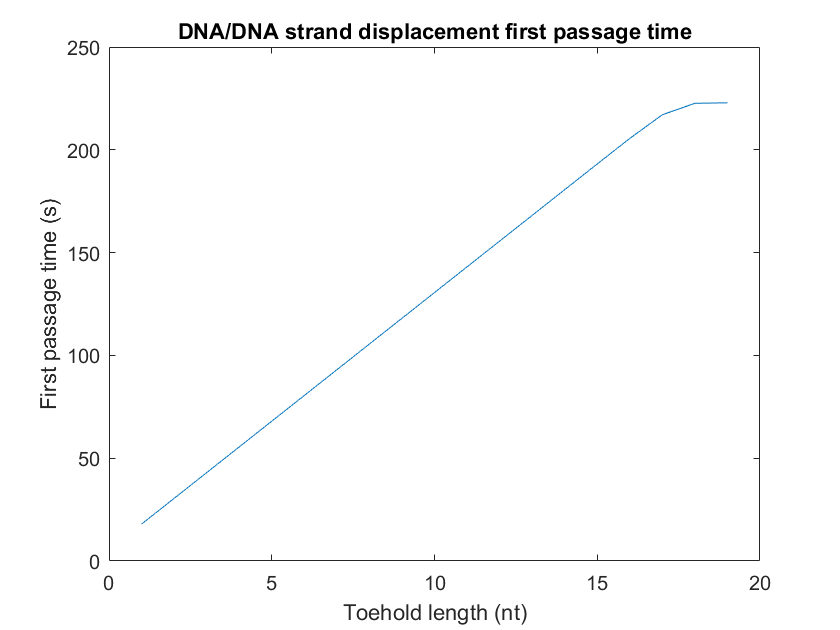

plot(1:19, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

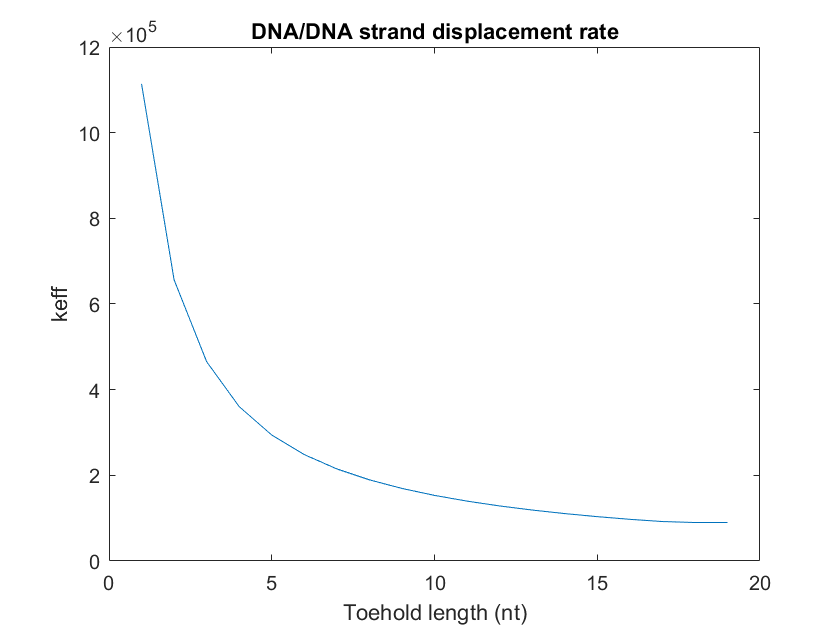


plot(1:19, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

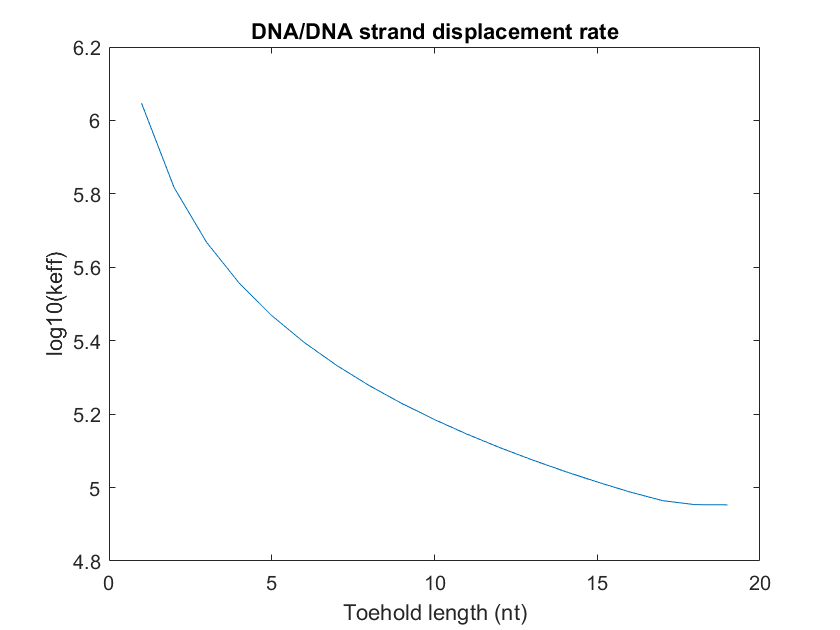


plot(1:19, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  

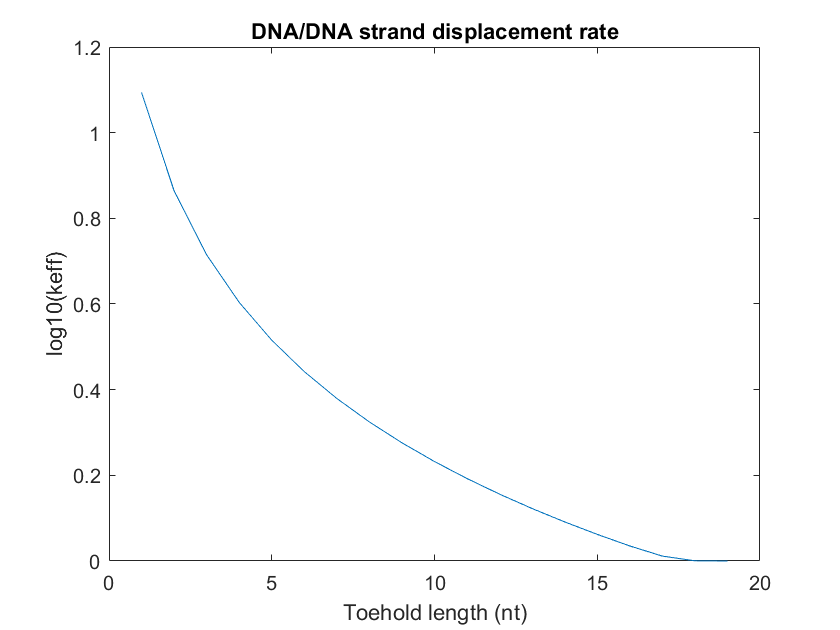


plot(1:19, log10(k_eff./k_eff_perf))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  